%This code reproduces Extended Fig1 from the second rebuttal submitted to Nature2020
%paper (Nienhuis et al., 2020). It needs v1 dataset provided by Jaap Nienhuis

v1 = load ('V1\GlobalDeltaData_v1.mat');%provided by Jaap Nienhuis
v11 = load ('V1.1\GlobalDeltaData.mat');
v2 = load ('V2\GlobalDeltaData.mat') %from https://github.com/jhnienhuis/GlobalDeltaChange

v2 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
           BasinID2: [10848×1 int64]
      BasinID_ATLAS: [10848×1 int64]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
                 Hs: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
              QWave: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
      RiverID_ATLAS: [1×10848 int64]
           TidalAmp: [10848×1 double]
                 Tp: [10848×1 double]
        channel_len: [10848×30 double]
    channel_len_lat: [10848×30 double]
    channel_len_lon: [10848×30 double]
      channel_slope: [10848×1 double]
         delta_name: [10848×1 s

v2.ee = load('V2\land_area_change\GlobalDeltaData_AreaChange.mat');
load 'V1/BasinID2';
BasinID2 = double(BasinID2);

%Max 100
Max_deltas100 = readtable('EE_Max100Big_polys_change.csv');

[~,DeltaID_Max100] = ismember(Max_deltas100.ID, BasinID2);


Max_deltas.Aqua = v1.ee.net_aqua(DeltaID_Max100);%GEt original land changes and data
Max_deltas.Pekel = v1.ee.net_pekel(DeltaID_Max100);
Max_deltas.Lat = v1.MouthLat(DeltaID_Max100);
Max_deltas.Lon = v1.MouthLon(DeltaID_Max100);
Max_deltas.Qdist = v1.QRiver_dist(DeltaID_Max100);
Max_deltas.Qprist = v1.QRiver_prist(DeltaID_Max100);
Max_deltas.Qwave = v1.QWave(DeltaID_Max100);
Max_deltas.Qtide = v1.QTide(DeltaID_Max100);

Max_deltas100_change = Max_deltas100.change2/28;


%Random108
rng(100) % seeds the random number generator with an arbitrary number (100) to get the same deltas each time
randomdeltas = randperm(10848, 108);

%Import 108 random deltas table
%GlobalDeltaData.mat from Nienhuis et al., 2020 needs to be imported
random108 = readtable('EE_108randomdeltas_ordered.csv'); %reads user filled-in table after check

%Get 44randomdeltas
random44poly = random108(random108.Polygon == 1, :);

%Import EE change into random44poly table
random44poly_change = readtable('EE_44polys_change.csv'); %loads Aqua changes obtained in EE

%EE_44polys_change.csv can be obtained by running the EE script located at:
%https://code.earthengine.google.com/1c074d96779371d7bf20922916ca22f9

%Add change to random44poly
[~,idrandom] = ismember(random44poly.BasinID, random44poly_change.BasinID); 
random44poly.change = random44poly_change.change2(idrandom)/28; %get yearly rates
random44poly.ero = random44poly_change.erosion2(idrandom)/28;
random44poly.dep = random44poly_change.deposition2(idrandom)/28;

%Add change from original Nienhuis buffers 
% ee from GlobalDeltaData.mat (Nienhuis et al., 2020) needs to be loade first
[~,idrandom_orig] = ismember(random44poly.BasinID, v1.BasinID); %get index for random44poly deltas in BasinID
random44poly.change_original = v1.ee.net_aqua(idrandom_orig);
random44poly.ero_original = v1.ee.ero_aqua(idrandom_orig);
random44poly.dep_original = v1.ee.dep_aqua(idrandom_orig);

%Compare net change
sum(random44poly.change) %not whole story

ans = 0.6065

sum(random44poly.change_original)

ans = 0.2093


%Create sorted min to max (based on original change) random44poly table
random44poly_sortchange = sortrows(random44poly,'change_original');
random44poly_sortchange = random44poly_sortchange([2 4:44 1 3], :); % move ee_delta 77 and 63 at end due to big new change value

random44_fit = fitlm(random44poly.change_original, random44poly.change) %R^2 = 0

random44_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue 
                   ________    _________    _______    _______

    (Intercept)    0.013172    0.0080208     1.6422    0.10802
    x1              0.12889      0.39253    0.32836    0.74427


Number of observations: 44, Error degrees of freedom: 42
Root Mean Squared Error: 0.0517
R-squared: 0.00256,  Adjusted R-Squared: -0.0212
F-statistic vs. constant model: 0.108, p-value = 0.744

%scatter(random44poly.change_original, random44poly.change)


%Figures

clf
figure

ax1 = subplot(1,4,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.1566 0.8150]
            Units: 'normalized'

  Show all properties


plot(Max_deltas.Aqua, Max_deltas100_change,'^','LineWidth',1)
xlabel 'Land change km^2/yr(Nienhuis et al.)'
ylabel 'Land change km^2/yr (This paper)'
h1 = lsline(ax1);
h1.Color = 'r';
grid off
zoom1 = Max_deltas.Aqua >= -0.5 & Max_deltas100_change <= 0.5;
text (Max_deltas.Aqua(~zoom1), Max_deltas100_change(~zoom1), Max_deltas100.NAME(~zoom1))
box on
axis square
xlim ([-10 20])
ylim ([-10 20])
line ([-10 20], [-10 20],'Color','k','LineStyle','--')
%symlog()

set(gcf,'color','white')
regression_Max = fitlm(Max_deltas.Aqua, Max_deltas100_change)

regression_Max = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)    0.69356     0.26775    2.5904      0.011147
    x1             0.57065     0.14921    3.8245    0.00023837


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.59
R-squared: 0.137,  Adjusted R-Squared: 0.128
F-statistic vs. constant model: 14.6, p-value = 0.000238

%NRMSEMax = 2.63./mean(Max_deltas100_change)
NRMSEMax_sd = 2.63./std(Max_deltas100_change)

NRMSEMax_sd = 0.9487

sum(Max_deltas.Aqua)

ans = 12.2899

sum(Max_deltas100_change)

ans = 72.2083


text(10, 18,'1:1 line')
text(-8, 17,'n=91')
text(-8, 16,'R^2=0.136')
text(-8, 14,'NRMSE_sd=0.93')
text(-8, 13,'ΣNienhuis net= 14.52 km^2/yr')
text(-8, 12,'ΣThis study net= 72.29 km^2/yr')


ax2 = subplot(1,4,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3361 0.1100 0.1566 0.8150]
            Units: 'normalized'

  Show all properties


plot(Max_deltas.Aqua(zoom1), Max_deltas100_change(zoom1),'^','LineWidth',1)
xlabel 'Land change km^2/yr(Nienhuis et al.)'
%ylabel 'Land change km^2/yr (This paper)'
h1 = lsline(ax2);
h1.Color = 'r';
grid off
zoom11 = Max_deltas.Aqua >= -0.5 & Max_deltas100_change <= 0.5;
text (Max_deltas.Aqua(zoom11), Max_deltas100_change(zoom11), Max_deltas100.NAME(zoom11))
box on
axis square
xlim ([-0.5 0.5])
ylim ([-0.5 0.5])
line ([-0.5 0.5], [-0.5 0.5],'Color','k','LineStyle','--')
%symlog()

set(gcf,'color','white')
regression_Max = fitlm(Max_deltas.Aqua(zoom1), Max_deltas100_change(zoom1))

regression_Max = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat     pValue 
                   ________    ________    ______    _______

    (Intercept)    0.040004    0.026446    1.5127    0.13468
    x1              0.13058     0.10603    1.2316    0.22205


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 0.216
R-squared: 0.0204,  Adjusted R-Squared: 0.00694
F-statistic vs. constant model: 1.52, p-value = 0.222

%NRMSEMax = 0.219./mean(Max_deltas100_change(zoom1))
NRMSEMax_sd = 0.219./std(Max_deltas100_change(zoom1))

NRMSEMax_sd = 1.0097

sum(Max_deltas.Aqua(zoom1))

ans = 6.1861

sum(Max_deltas100_change(zoom1))

ans = 3.8081


text(10, 18,'1:1 line')
text(-8, 17,'n=73')
text(-8, 16,'R^2=0')
text(-8, 14,'NRMSE=15.29')
%text(-8, 13,'ΣNienhuis net= 11.82 km^2/yr')
%text(-8, 12,'ΣBesset net= 24.45 km^2/yr')


ax3 = subplot(1,4,3)

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.1100 0.1566 0.8150]
            Units: 'normalized'

  Show all properties


plot(random44poly.change_original, random44poly.change,'^','LineWidth',1)
xlabel 'Land change km^2/yr(Nienhuis et al.)'
%ylabel 'Random108 (km^2/yr)'
h1 = lsline(ax3);
h1.Color = 'r';
grid off

[~,idrandom_name] = ismember(random44poly.BasinID, v11.BasinID);
random44poly_name = v11.delta_name(idrandom_name);
zoom2 = random44poly.change_original >= -0.2 & random44poly.change <= 0.2;
text (random44poly.change_original(~zoom2), random44poly.change(~zoom2), random44poly_name(~zoom2))
box on
axis square
xlim ([-0.05 0.3])
ylim ([-0.05 0.3])
%line ([-10 10], [-10 10],'Color','k','LineStyle','--')
%symlog()

set(gcf,'color','white')
regression_Max = fitlm(random44poly.change_original, random44poly.change)

regression_Max = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue 
                   ________    _________    _______    _______

    (Intercept)    0.013172    0.0080208     1.6422    0.10802
    x1              0.12889      0.39253    0.32836    0.74427


Number of observations: 44, Error degrees of freedom: 42
Root Mean Squared Error: 0.0517
R-squared: 0.00256,  Adjusted R-Squared: -0.0212
F-statistic vs. constant model: 0.108, p-value = 0.744

%NRMSEMax = ./mean(random44poly.change)
NRMSEMax_sd = 0.0517./std(random44poly.change)

NRMSEMax_sd = 1.0097

sum(random44poly.change_original)

ans = 0.2093

sum(random44poly.change)

ans = 0.6065


text(20, 18,'1:1 line')
text(-8, 17,'n=44')
text(-8, 16,'R^2=0')
%text(-8, 15,'p=0.186')
text(-8, 14,'NRMSE=1.19')
%text(-8, 13,'ΣNienhuis net= 11.82 km^2/yr')
%text(-8, 12,'ΣBesset net= 24.45 km^2/yr')


ax4 = subplot(1,4,4)

ax4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.8150]
            Units: 'normalized'

  Show all properties


zoom2 = random44poly.change_original >= -0.01 & random44poly.change <= 0.01;

plot(random44poly.change_original(zoom2), random44poly.change(zoom2),'^','LineWidth',1)
xlabel 'Land change km^2/yr(Nienhuis et al.)'
%ylabel 'Random108 (km^2/yr)'
h1 = lsline(ax4);
h1.Color = 'r';
grid off
%random44poly_name = v11.delta_name(idrandom_name);
%text (random44poly.change_original(zoom2), random44poly.change(zoom2), random44poly_name(zoom2))
box on
axis square
xlim ([-0.01 0.01])
ylim ([-0.01 0.01])
line ([-0.01 0.01], [-0.01 0.01],'Color','k','LineStyle','--')
%symlog()

set(gcf,'color','white')
regression_Max = fitlm(random44poly.change_original(zoom2), random44poly.change(zoom2))

regression_Max = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat      pValue 
                   ___________    __________    ________    _______

    (Intercept)    -0.00022979    0.00056152    -0.40922    0.68487
    x1                0.029909      0.034119     0.87662    0.38667


Number of observations: 37, Error degrees of freedom: 35
Root Mean Squared Error: 0.00338
R-squared: 0.0215,  Adjusted R-Squared: -0.00647
F-statistic vs. constant model: 0.768, p-value = 0.387

%NRMSEMax = 0.0033./mean(random44poly.change(zoom2))
NRMSEMax_sd = 0.0033./std(random44poly.change(zoom2))

NRMSEMax_sd = 0.9785

sum(random44poly.change_original(zoom2))

ans = 0.0833

sum(random44poly.change(zoom2))

ans = -0.0060


text(10, 18,'1:1 line')
text(-8, 17,'n=37')
text(-8, 16,'R^2=0.02')
%text(-8, 15,'p=0.186')
text(-8, 14,'NRMSE=996')
%text(-8, 13,'ΣNienhuis net= 11.82 km^2/yr')
%text(-8, 12,'ΣBesset net= 24.45 km^2/yr')

% 
% ax2 = subplot(1,3,2)
% plot(random44poly.change_original, random44poly.change,'^','LineWidth',1)
% xlabel 'Nienhuis (km^2/yr)'
% ylabel 'Random108 (km^2/yr)'
% h1 = lsline(ax2);
% h1.Color = 'r';
% grid off
% %zoom = Big_deltas.Net_change_km2_yr >= -1 & Big_deltas.Net_change_km2_yr <= 1;
% %text (Big_deltas.Aqua(~zoom), Big_deltas.Net_change_km2_yr(~zoom), Big_deltas.DELTA(~zoom))
% box on
% axis square
% xlim ([-0.05 0.3])
% ylim ([-0.05 0.3])
% %line ([-10 10], [-10 10],'Color','k','LineStyle','--')
% %symlog()

set(gcf,'color','white')
regression_Max = fitlm(Max_deltas.Aqua, Max_deltas100_change)

regression_Max = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)    0.69356     0.26775    2.5904      0.011147
    x1             0.57065     0.14921    3.8245    0.00023837


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.59
R-squared: 0.137,  Adjusted R-Squared: 0.128
F-statistic vs. constant model: 14.6, p-value = 0.000238

NRMSEMax = 3.36./mean(Max_deltas100_change)

NRMSEMax = 4.3740

NRMSEMax_sd = 3.36./std(Max_deltas100_change)

NRMSEMax_sd = 1.2120

ans = 12.2899

ans = 72.2083

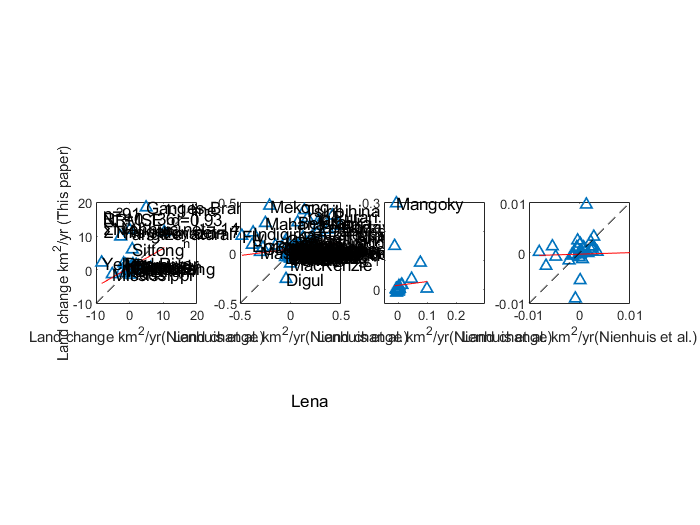


text(10, 18,'1:1 line')
text(-8, 17,'n=92')
text(-8, 16,'R^2=0.06')
text(-8, 15,'p=0.186')
text(-8, 14,'NRMSE=12.63')

%text(-8, 13,'ΣNienhuis net= 11.82 km^2/yr')
%text(-8, 12,'ΣBesset net= 24.45 km^2/yr')

% ax3 = subplot(1,3,3)
% plot(Big_deltas.Aqua, Big_deltas.Net_change_km2_yr,'^','LineWidth',1)
% xlabel 'Nienhuis (km^2/yr)'
% ylabel 'Besset (km^2/yr)'
% h1 = lsline(ax3);
% h1.Color = 'r';
% grid off
% zoom = Big_deltas.Net_change_km2_yr >= -0.5 & Big_deltas.Net_change_km2_yr <= 0.5;
% text (Big_deltas.Aqua(~zoom), Big_deltas.Net_change_km2_yr(~zoom), Big_deltas.DELTA(~zoom))
% box on
% axis square
% xlim ([-10 20])
% ylim ([-10 20])
% line ([-10 20], [-10 20],'Color','k','LineStyle','--')
% text(10, 18,'1:1 line')
% text(-8, 17,'n=48')
% text(-8, 16,'R^2=0.038')
% text(-8, 15,'p=0.184')
% text(-8, 14,'NRMSE=8.3')
% text(-8, 13,'ΣNienhuis net= 2.3 km^2/yr')
% text(-8, 12,'ΣBesset net= 19.4 km^2/yr')
% set(gcf,'color','white')
% regression_Big = fitlm(Big_deltas.Aqua, Big_deltas.Net_change_km2_yr)
% NRMSEbig = 3.36./mean(Big_deltas.Net_change_km2_yr)
% NRMSEbig_sd = 3.36./std(Big_deltas.Net_change_km2_yr)
% sum(Big_deltas.Aqua)
% sum(Big_deltas.Net_change_km2_yr)
